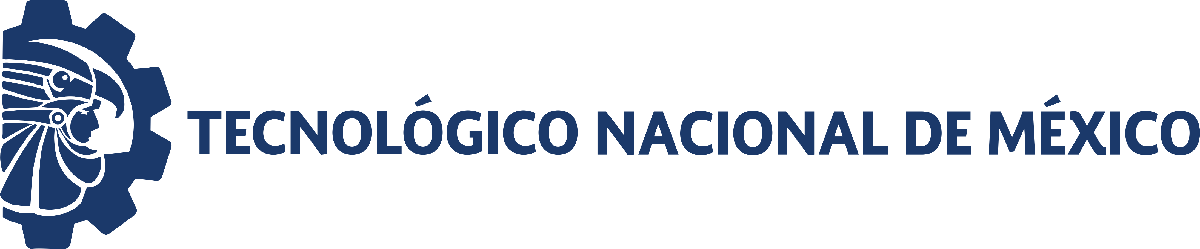                                 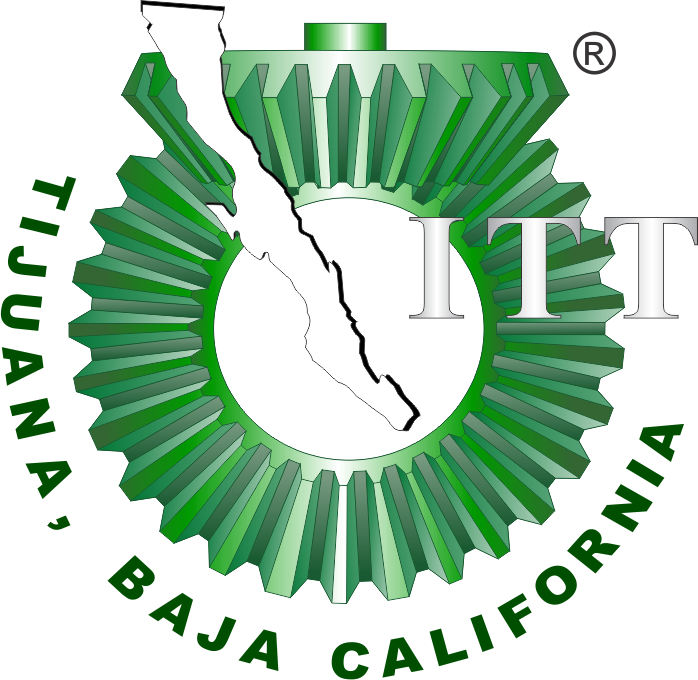

# Práctica 1: Leyes de crecimiento exponencial

**Departamento de Ingeniería Eléctrica y Electrónica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

[Foto]

Nombre del alumno: **Gianna Victoria Adame**

Número de control: **20212527**

Correo institucional: **L20212527@tectijuana.edu.mx**

Carrera: **Ingeniería Biomédica**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Simulation data

clc; clear; close all; warning('off','all')

## Exponential growth


$$\dot{x} =\textrm{kx}$$


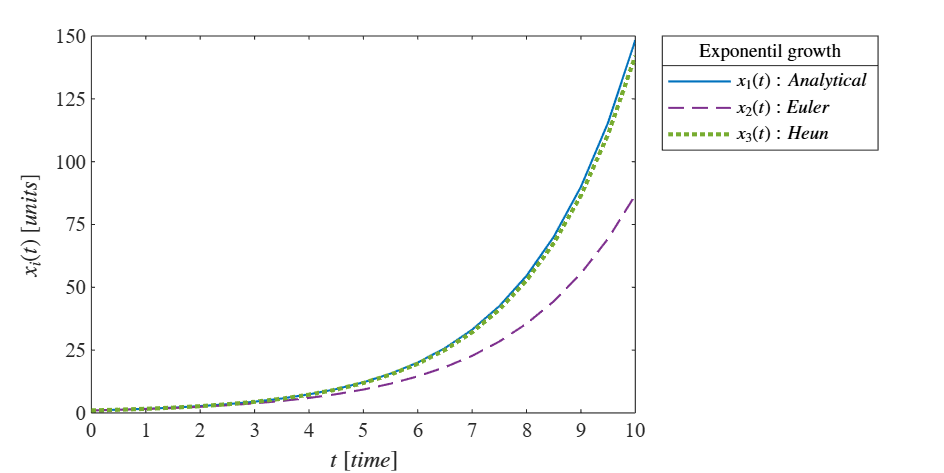

dt = 0.5; %Integration step
x0 = 1; %Initial condition
k = 0.5; %Growth rate (parameter)
tend = 10; %Simulation final time

[t,x1,x2,x3] = sys_expgrowth(dt,x0,k,tend);
plotl1(t,x1,x2,x3);

## Exponential decay


$$\dot{x} =-\textrm{kx}$$


Look for the point in the plot where $x\left(t\right)\frac{x_0 }{2}$ (half-life, $t_{\frac{1}{2}}$) and compute the decay rate of the bioprocess, where k = $\frac{\textrm{ln2}}{t_{\frac{1}{2}} }$.

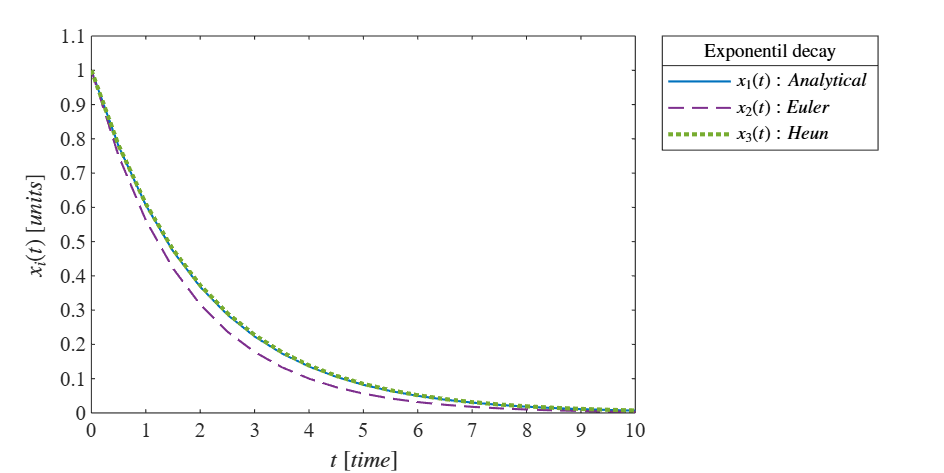

dt = 0.5; %Integration step
x0 = 1; %Initial condition
k = 0.5; %Growth rate (parameter)
tend = 10; %Simulation final time

[t,x1,x2,x3] = sys_expdecay(dt,x0,k,tend);
plotl2(t,x1,x2,x3);

## First-order pharmacokinetics [modified exponential decay]: Controlled drug delivery by nanohydrogels


$$\dot{x} =\beta \left(1-e^{-\textrm{kt}} \right)$$


**Reference: **González‐Ayón, M. A., Sañudo‐Barajas, J. A., Picos‐Corrales, L. A., & Licea‐Claverie, A. (2015). PNVCL‐PEGMA nanohydrogels with tailored transition temperature for controlled delivery of 5‐fluorouracil. *Journal of Polymer Science Part A: Polymer Chemistry*, *53*(22), 2662-2672. doi:  10.1002/pola.27766

### Experimental data

clc; clear; close all
sys = readmatrix('data.csv');
t = round(sys(:,1));
x1 = sys(:,2); x2 = sys(:,3); x3 = sys(:,4); x4 = sys(:,5);
T = array2table([t,x1,x2,x3,x4],'VariableNames',{'t [min]', 'N32', 'N35', 'N36', 'N45'}); disp (T)

    t [min]     N32      N35      N36      N45 
    _______    _____    _____    _____    _____

        0          0        0        0        0
       15      43.68    35.47    51.35    34.39
       30      64.31    55.89    69.07    49.08
       45       73.6    62.69    77.82    59.34
       60      80.95    70.15     84.3    68.31
       75      82.24    72.85     88.4    72.85
       91      85.59    75.44    92.07    76.74
      105       88.4    77.92    95.42    80.08
      120      90.56    78.03    97.15    83.65
      150      90.78    80.52    97.69    86.78
      180      90.24    80.73    97.69    88.83
      210       92.4     80.3    98.23    89.91



### Nonlinear regression and biotatistics

rho = [0.1, 100];
mdl_x1 = pharmacokinetics(t,x1,rho); y1 = mdl_x1.Fitted; % Nanohydrogel N32


Sample size (n): 12
Parameters to be estimated (pars): 2
Degrees of freedom: 10
Significance level (alpha): 0.05
t-Student value:2.2281
Adjusted R-squared:0.99485
Corrected AIC (n/pars < 40):    Parameters    Estimate       SE           MoE               CI95              pvalue  
    __________    ________    _________    _________    ____________________    __________

       k          0.040504    0.0017568    0.0039143    0.036589    0.044418    5.3239e-10
       beta         89.847      0.82673       1.8421      88.004      91.689    1.0668e-16



mdl_x2 = pharmacokinetics(t,x2,rho); y2 = mdl_x2.Fitted; % Nanohydrogel N35


Sample size (n): 12
Parameters to be estimated (pars): 2
Degrees of freedom: 10
Significance level (alpha): 0.05
t-Student value:2.2281
Adjusted R-squared:0.99627
Corrected AIC (n/pars < 40):    Parameters    Estimate       SE           MoE               CI95              pvalue  
    __________    ________    _________    _________    ____________________    __________

       k          0.037453    0.0013753    0.0030643    0.034388    0.040517    1.0315e-10
       beta         79.417      0.65053       1.4495      77.967      80.866    3.3367e-17



mdl_x3 = pharmacokinetics(t,x3,rho); y3 = mdl_x3.Fitted; % Nanohydrogel N36


Sample size (n): 12
Parameters to be estimated (pars): 2
Degrees of freedom: 10
Significance level (alpha): 0.05
t-Student value:2.2281
Adjusted R-squared:0.98763
Corrected AIC (n/pars < 40):    Parameters    Estimate       SE           MoE               CI95              pvalue  
    __________    ________    _________    _________    ____________________    __________

       k          0.041963    0.0028129    0.0062676    0.035695     0.04823     3.686e-08
       beta         95.959       1.3342       2.9728      92.986      98.932    6.5864e-15



mdl_x4 = pharmacokinetics(t,x4,rho); y4 = mdl_x4.Fitted; % Nanohydrogel N45


Sample size (n): 12
Parameters to be estimated (pars): 2
Degrees of freedom: 10
Significance level (alpha): 0.05
t-Student value:2.2281
Adjusted R-squared:0.99032
Corrected AIC (n/pars < 40):    Parameters    Estimate       SE           MoE               CI95              pvalue  
    __________    ________    _________    _________    ____________________    __________

       k          0.025988    0.0015189    0.0033843    0.022604    0.029373    9.8118e-09
       beta         87.728       1.4513       3.2337      84.494      90.962    3.7311e-14



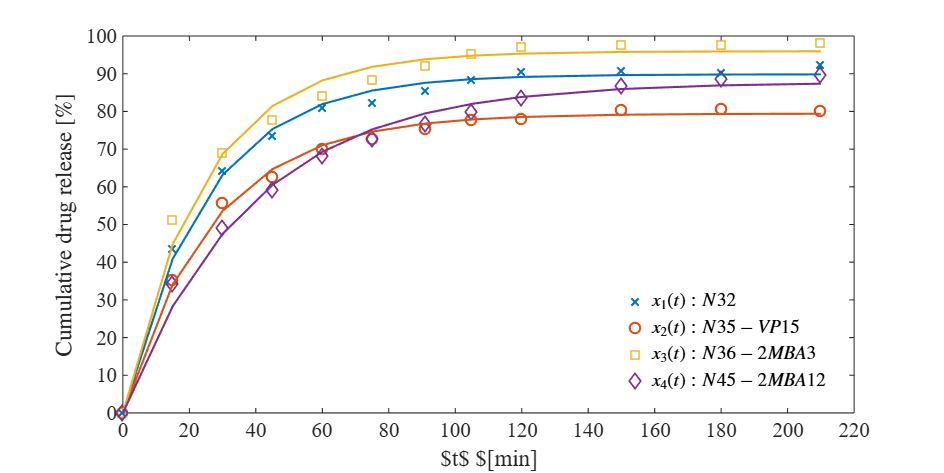

plotdata(t,x1,x2,x3,x4,y1,y2,y3,y4);

### Functions

function mdl = pharmacokinetics (to,xo,rho)

    function xi = model(rho,t)
        k = rho(1); beta = rho (2);
        xi = beta*(1 - exp(-k*t));
    end

    mdl = fitnlm(to,xo,@model,rho);

   Estimate = table2array(mdl.Coefficients(:,1));
   SE = table2array(mdl.Coefficients(:,2));
   pvalue = table2array(mdl.Coefficients(:,4));
   alpha = 0.05;
   CI95 = coefCI(mdl,alpha);
   dof = mdl.DFE;
   tval = tinv(1 - alpha/2,dof);
   MoE = SE*tval;
   Parameters = ['k   ';'beta'];
   Results = table(Parameters,Estimate,SE,MoE,CI95,pvalue);

   fprintf(['\nSample size (n): ', num2str(numel(xo))])
   fprintf(['\nParameters to be estimated (pars): ', num2str(numel(rho))])
   fprintf(['\nDegrees of freedom: ', num2str(dof)])
   fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
   fprintf(['\nt-Student value:', num2str(tval)])
   fprintf(['\nAdjusted R-squared:', num2str(mdl.Rsquared.Adjusted)])
   fprintf(['\nCorrected AIC (n/pars < 40):'], num2str(mdl.ModelCriterion.AIC), '\n\n')

   disp(Results)

end 

function plotdata(t,x1,x2,x3,x4,y1,y2,y3,y4)
set(figure(3),'color','w')
set(gcf,'units','centimeters','position',[2,2,20,10])
set(gca,'Fontname','Times New Roman')
fontsize(10,'points')
mycolors = [0 0.4470 0.7410;
            0.8500 0.3250 0.0980; 
            0.9290 0.6940 0.1250;
            0.4940 0.1840 0.5560]; 
        hold on; box on; grid off; colororder(mycolors)
        %Experimental data
        plot(t,x1,'x','MarkerSize',5,'LineWidth',1)
        plot(t,x2,'o','MarkerSize',5,'LineWidth',1)
        plot(t,x3,'square','MarkerSize',5,'LineWidth',1)
        plot(t,x4,'diamond','MarkerSize',5,'LineWidth',1)
        %Fitted value
        plot(t,y1,'-','LineWidth',1)
        plot(t,y2,'-','LineWidth',1)
        plot(t,y3,'-','LineWidth',1)
        plot(t,y4,'-','LineWidth',1)

        xlabel('$t$ $[min]', 'Interpreter','latex')
        ylabel('Cumulative drug release $[\%]$','Interpreter','latex')
        xlim([0,220]);xticks(0:20:220)
        ylim([0 100]);yticks(0:10:100)

        L = legend('$x_1(t):N32$','$x_2(t):N35-VP15$','$x_3(t):N36-2MBA3$','$x_4(t):N45-2MBA12$');
        set(L,'Interpreter','latex','Location','SouthEast','Box','Off')

        exportgraphics(gcf,'nanohydrogels.pdf','ContentType','Vector')
        exportgraphics(gcf,'nanohydrogels.png','Resolution',600)
        exportgraphics(gcf,'nanohydrogels.jpg','Resolution',600)
        print('nanohydrogels','-dsvg')
        print('nanohydrogels','-depsc')
end

### Chemotherapy dynamics in the blood compartment

Assume thtat the chemotherapy drug within the blood compartment follows a first-order kinetics. Let us apply the modified exponential decay to illustrate the dynamics of this drug when administered with the following scheme:

- **Protocol:** (3 Imatinib intakes every 2 days + 7 days of rest)* 2 cycles.

- **Dosing:** 3000 mg/day per dose.

- **Application frequency:** One dose every 2 days.

- **Doses per cycle:** 3 doses.

- **Number of cycles:** 2 cycles.

- **Imatinib biological half life [**$t_{1/2}$**]: **18 hourse [0.75 days].                                           [https://go.drugbank.com/drugs/DB00619](https://go.drugbank.com/drugs/DB00619)

- **ODE:** $x=\phi \left(t\right)-\mu x$

### Time: Hours

dt = 0.01; dose = 300; mu= log(2)/18 ; tend = 21*24;

Function definitions in a script must appear at the end of the file.
Move all statements after the "plotdata" function definition to before the first local function definition.

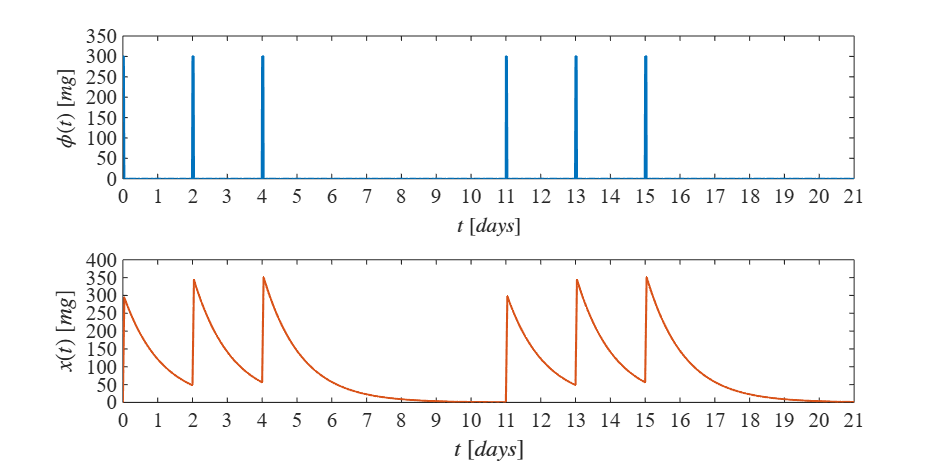


phi = zeros(tend/dt+1,1);
%Cycle 1 
phi(1:1/dt) = dose;
phi(2*24/dt:(2*24+1)/dt) = dose;
phi(4*24/dt:(4*24+1)/dt) = dose;
% Cycle 2 
phi(11*24/dt:(11*24+1)/dt) = dose;
phi(13*24/dt:(13*24+1)/dt) = dose;
phi(15*24/dt:(15*24+1)/dt) = dose;

[t,x] = sys_chemo(dt,mu,phi,tend);
plotchemo(t/24,phi,x,'hours')

### Time:days

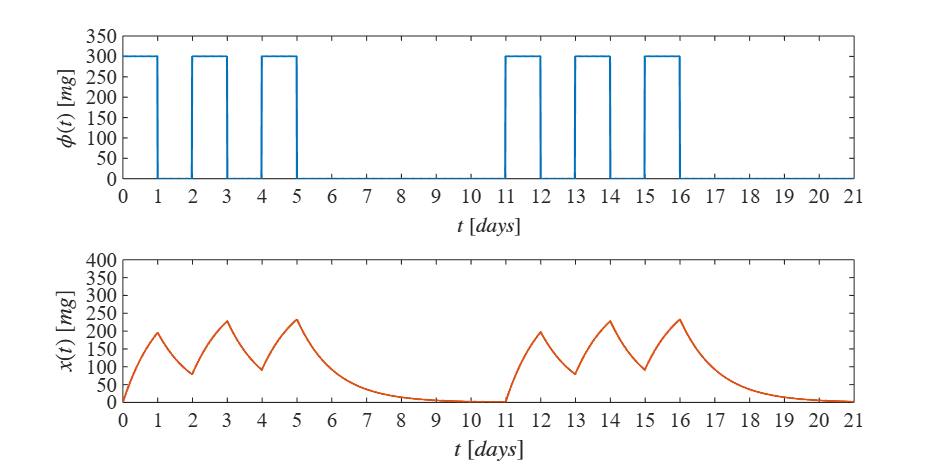

dt = 0.01; dose = 300; mu= log(2)/(18/24) ; tend = 24;

phi = zeros(tend/dt+1,1);
%Cycle 1 
phi(1:1/dt) = dose;
phi(2/dt:(3)/dt) = dose;
phi(4/dt:(5)/dt) = dose;
% Cycle 2 
phi(11/dt:12/dt) = dose;
phi(13/dt:14/dt) = dose;
phi(15/dt:16/dt) = dose;

[t,x] = sys_chemo(dt,mu,phi,tend);
plotchemo(t,phi,x,'days')

### Function

function [t,x] = sys_chemo(dt,mu,phi,tend)
t = (0:dt:tend)';
n = round(tend/dt);
x = zeros(numel(t),1);

%Heun's method
    for i=1:n
        [fx] = f(x(i), phi(i));
        xn = x(i)+ fx*dt;
        [fxn]= f(xn,phi(i));

        x(i+1) = x(i) + (fx + fxn)*dt/2;
    end
    function [dx] = f(x,phi)
            dx = phi - mu*x;
    end
end

function plotchemo(t,phi,x,time)
    set(figure(),'color','w')
    set(gcf,'units','centimeters','position',[2,2,20,10])

    subplot(2,1,1)
    set(gca,'Fontname','Times New Roman')
    fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,phi,'-','LineWidth',1, 'Color',[0,0.4470,0.7410])
    xlabel('$t$ $[days]$', 'Interpreter','latex')
    ylabel('$\phi(t)$ $[mg]$','Interpreter','latex')
    xlim([0 21]); xticks(0:1:21)
    ylim([0 350]); yticks(0:50:350)

    subplot(2,1,2)
    set(gca,'Fontname','Times New Roman')
    fontsize(10,'points')
    hold on; box on; grid off; 
    plot(t,x,'-','LineWidth',1, 'Color',[0.8500,0.3250,0.0980])
    xlabel('$t$ $[days]$', 'Interpreter','latex')
    ylabel('$x(t)$ $[mg]$','Interpreter','latex')
    xlim([0 21]); xticks(0:1:21)
    ylim([0 400]); yticks(0:50:400)

    exportgraphics(gcf,['chemo', time ,'.pdf'],'ContentType','vector')

end

Functions

function [t,x1,x2,x3] = sys_expgrowth(dt,x0,k,tend)
    t = (0:dt:tend);
    n = round(tend/dt);
    x2 = zeros(numel(t),1); x2 = x0;
    x3 = zeros(numel(t),1); x3 = x0;

    %% Analytical solution
    x1 = x0*exp(k*t);

    %% Euler's method 
    for i = 1:n
        x2(i+1) = x2(i) + (k*x2(i))*dt;
    end

    %%Heun's method
    for i = 1:n
        [fx3] = f(x3(i));
        x3n = x3(i) + fx3*dt;

        [fx3n] = f(x3n);
        x3(i+1) = x3(i) + (fx3 + fx3n)*dt/2;
    end

    function [dx3] = f(x3)
        dx3 = k*x3;
    end

end

function plotl1(t,x1,x2,x3)
    set(figure(1),'Color','w')
    set(gcf, 'Units', 'Centimeters','Position',[2,2,20,10])
    set(gca,'FontName','Times New Roman')
    fontsize(10,'points')
    mycolors = [0,0.4470,0.7410;0.4940,0.1840,0.5560;0.4660,0.6740,0.1880];
    hold on; box on; grid off; colororder(mycolors)
    
    plot (t,x1,'-','LineWidth',1)
    plot (t,x2,'--','LineWidth',1)
    plot (t,x3,':','LineWidth',2)
    xlabel('$t$ $[time]$','Interpreter', 'latex')
    ylabel('$x_i(t)$ $[units]$', 'Interpreter', 'latex')
    L = legend('$x_1(t):Analytical$','$x_2(t):Euler$','$x_3(t):Heun$');
    set(L, 'Interpreter','latex','Location','NorthEastOutside')
    title(L,'Exponentil growth')
    xlim([0 10]); xticks(0:1:10)
    ylim([0 150]); yticks (0:25:150)


    exportgraphics(gcf,'exponential growth.pdf','ContentType','vector')
end

function [t,x1,x2,x3] = sys_expdecay(dt,x0,k,tend)
    t = (0:dt:tend)';
    n = round(tend/dt);
    x2 = zeros(numel(t),1); x2 = x0;
    x3 = zeros(numel(t),1); x3 = x0;

    %% Analytical solution
    x1 = x0*exp(-k*t);

    %% Euler's method 
    for i = 1:n
        x2(i+1) = x2(i) + (-k*x2(i))*dt;
    end

    %%Heun's method
    for i = 1:n
        [fx3] = f(x3(i));
        x3n = x3(i) + fx3*dt;

        [fx3n] = f(x3n);
        x3(i+1) = x3(i) + (fx3 + fx3n)*dt/2;
    end

    function [dx3] = f(x3)
        dx3 = -k*x3;
    end

end

function plotl2(t,x1,x2,x3)
    set(figure(2),'Color','w')
    set(gcf, 'Units', 'Centimeters','Position',[2,2,20,10])
    set(gca,'FontName','Times New Roman')
    fontsize(10,'points')
    mycolors = [0,0.4470,0.7410;0.4940,0.1840,0.5560;0.4660,0.6740,0.1880];
    hold on; box on; grid off; colororder(mycolors)
    
    plot (t,x1,'-','LineWidth',1)
    plot (t,x2,'--','LineWidth',1)
    plot (t,x3,':','LineWidth',2)
    xlabel('$t$ $[time]$','Interpreter', 'latex')
    ylabel('$x_i(t)$ $[units]$', 'Interpreter', 'latex')
    L = legend('$x_1(t):Analytical$','$x_2(t):Euler$','$x_3(t):Heun$');
    set(L, 'Interpreter','latex','Location','NorthEastOutside')
    title(L,'Exponentil decay')
    xlim([0 10]); xticks(0:1:10)
    ylim([0 1.1]); yticks (0:0.1:1.1)


    exportgraphics(gcf,'exponential decay.pdf','ContentType','vector')
end